close all; 
clear all; 
clc; 

original  = imread('hw2_files\Q2\girl.jpeg');
original = im2double(original);
[row,col,~] = size(original)

row = 503

col = 386

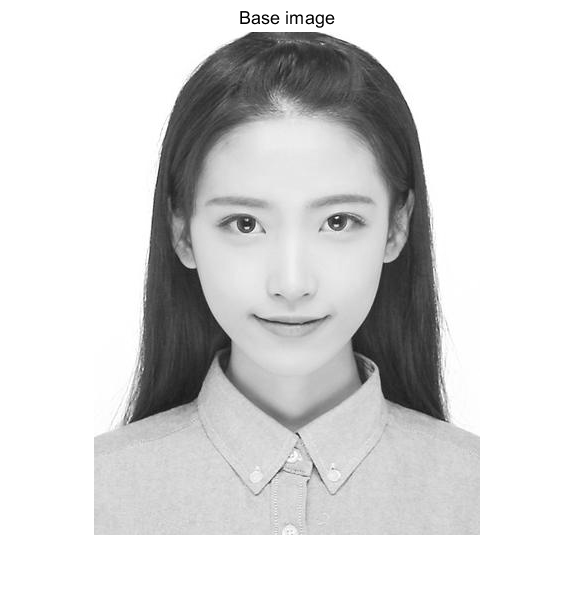

original = rgb2gray(original);
imshow(original); 
title('Base image'); 

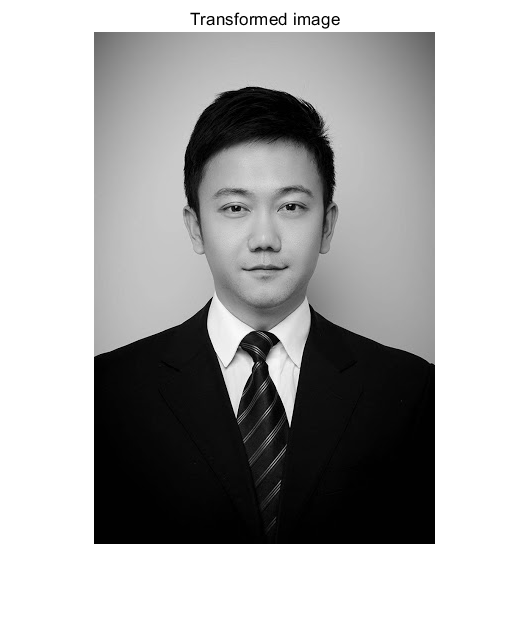


% distorted = imresize(original,0.7); 
% distorted = imrotate(distorted,31); 
distorted = imread('hw2_files\Q2\man.jpg'); 
distorted = rgb2gray(distorted);
distorted = im2double(distorted);
figure; 
imshow(distorted); 
title('Transformed image'); 


faceDetector = vision.CascadeObjectDetector;

bboxes_g = step(faceDetector, original)

bboxes_g =     76    99   243   243


bboxes_m = step(faceDetector, distorted)

bboxes_m =     92   115   156   156



ori_onlyFace = ones([row,col])*255;
dis_onlyFace = ones([row,col])*255;

ori_onlyFace(bboxes_g(1,2):bboxes_g(1,2)+bboxes_g(1,4),bboxes_g(1,1):bboxes_g(1,1)+bboxes_g(1,3))=original(bboxes_g(1,2):bboxes_g(1,2)+bboxes_g(1,4),bboxes_g(1,1):bboxes_g(1,1)+bboxes_g(1,3))

ori_onlyFace =    255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   2

dis_onlyFace(bboxes_m(1,2):bboxes_m(1,2)+bboxes_m(1,4),bboxes_m(1,1):bboxes_m(1,1)+bboxes_m(1,3))=distorted(bboxes_m(1,2):bboxes_m(1,2)+bboxes_m(1,4),bboxes_m(1,1):bboxes_m(1,1)+bboxes_m(1,3))

dis_onlyFace =    255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   2

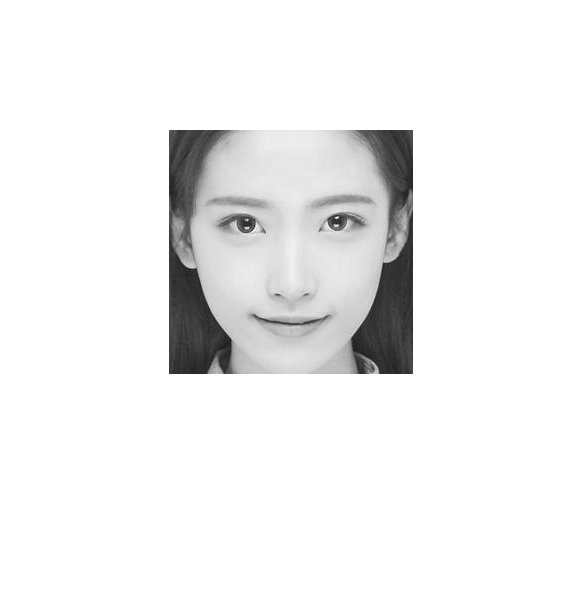

imshow(ori_onlyFace);

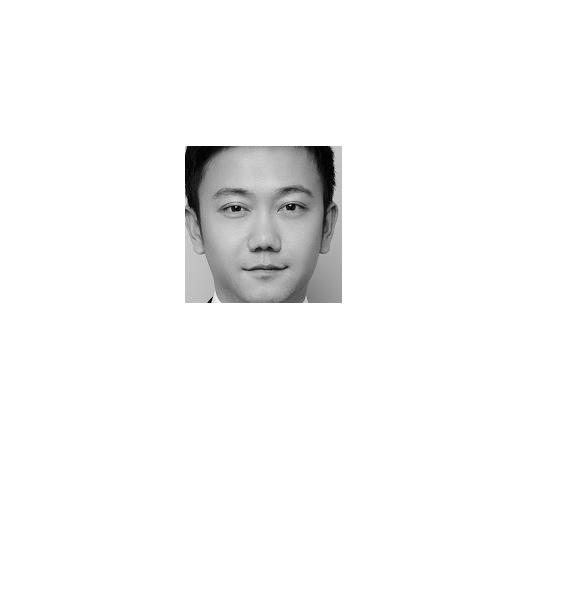

imshow(dis_onlyFace);

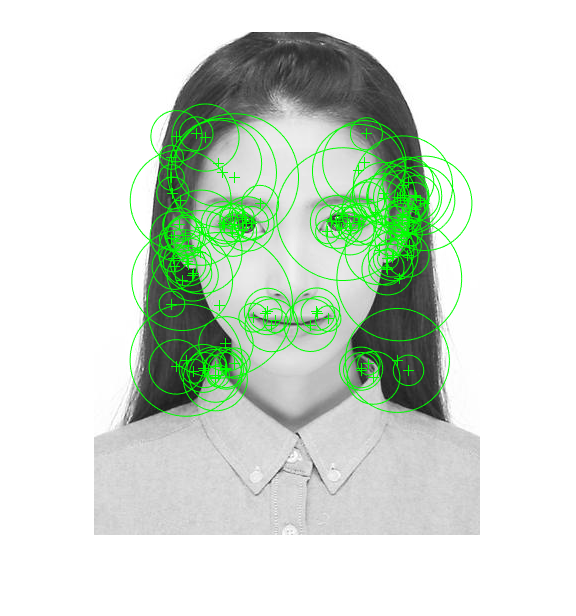

% Extract surf key points
ptsOriginal = detectSURFFeatures(ori_onlyFace); 
ptsDistorted = detectSURFFeatures(dis_onlyFace); 
figure;imshow(original); hold on;
plot(ptsOriginal);

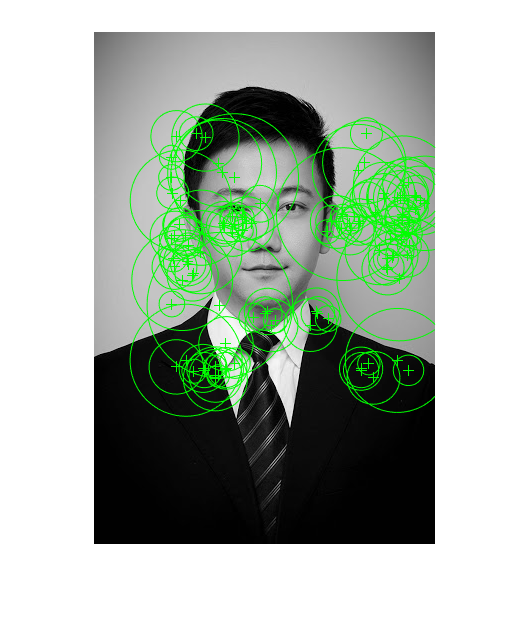

figure;imshow(distorted); hold on;
plot(ptsOriginal);

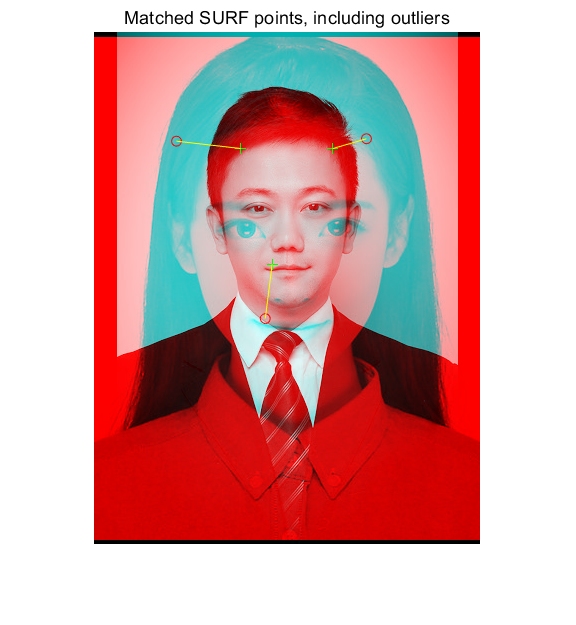

% Generate descriptive features
[featuresOriginal,validPtsOriginal] = extractFeatures(original,ptsOriginal); 
[featuresDistorted,validPtsDistorted] = extractFeatures(distorted,ptsDistorted);
% Descriptive feature matching
index_pairs = matchFeatures(featuresOriginal,featuresDistorted); 

% Matched key points
matchedPtsOriginal = validPtsOriginal(index_pairs(:,1)); 
matchedPtsDistorted = validPtsDistorted(index_pairs(:,2)); 

%Show matching points
figure;
showMatchedFeatures(original,distorted,matchedPtsOriginal,matchedPtsDistorted);
title('Matched SURF points, including outliers'); 

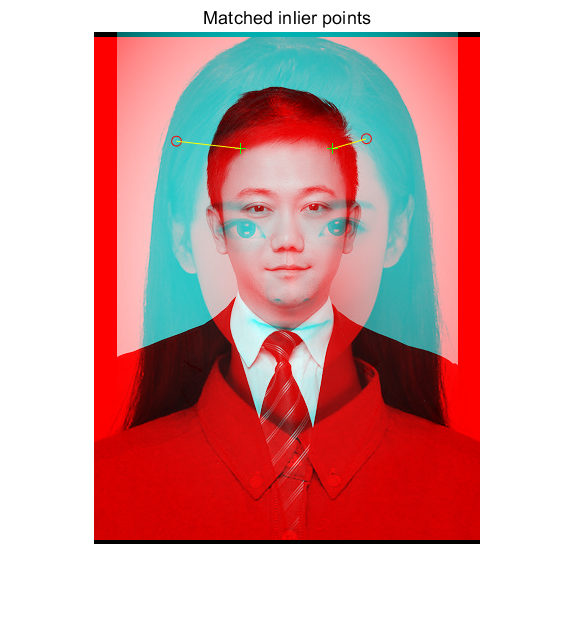


%Estimate geographic transform matrix
[tform,inlierPtsDistorted,inlierPtsOriginal] = estimateGeometricTransform(matchedPtsDistorted,matchedPtsOriginal,'similarity'); 
[tform_project,inlierPtsDistorted,inlierPtsOriginal] = estimateGeometricTransform(matchedPtsDistorted,matchedPtsOriginal,'similarity');
figure;
showMatchedFeatures(original,distorted,inlierPtsOriginal,inlierPtsDistorted); 
title('Matched inlier points'); 

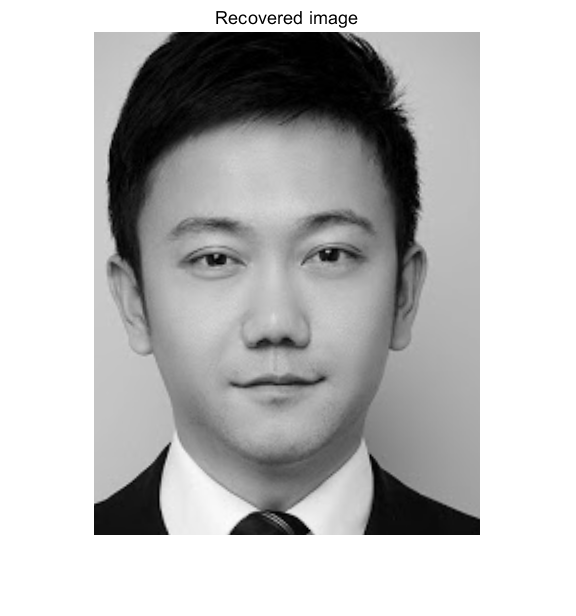


%Compute the estimated registration result
outputView = imref2d(size(original)); 
Ir = imwarp(distorted,tform,'OutputView',outputView); 
figure; 
imshow(Ir); 
title('Recovered image'); 

stitch_img = zeros([row,col])

stitch_img =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0

stitch_img(1:row,1:col/2) = Ir(1:row,1:col/2);
stitch_img(1:row,col/2+1:col) = original(1:row,col/2+1:col)

stitch_img =     0.7373    0.7373    0.7373    0.7378    0.7383    0.7383    0.7383    0.7396    0.7410    0.7416    0.7422    0.7434    0.7447    0.7451    0.7451    0.7455    0.7462    0.7472    0.7484    0.7490    0.7490    0.7490    0.7490    0.7490    0.7490    0.7490    0.7490    0.7495    0.7514    0.7529    0.7529    0.7531    0.7539    0.7548    0.7558    0.7569    0.7569    0.7569    0.7569    0.7569    0.7569    0.7569    0.7569    0.7569    0.7569    0.7569    0.7576    0.7586    0.7596    0.7604
    0.7373    0.7373    0.7373    0.7387    0.7401    0.7402    0.7402    0.7407    0.7411    0.7424    0.7439    0.7446    0.7450    0.7451    0.7451    0.7461    0.7477    0.7485    0.7489    0.7490    0.7490    0.7490    0.7490    0.7490    0.7490    0.7490    0.7490    0.7495    0.7514    0.7529    0.7529    0.7532    0.7549    0.7566    0.7568    0.7569    0.7569    0.7569    0.7569    0.7569    0.7569    0.7569    0.7569    0.7569    0.7569    0.7569    0.7582    0.7601    0.

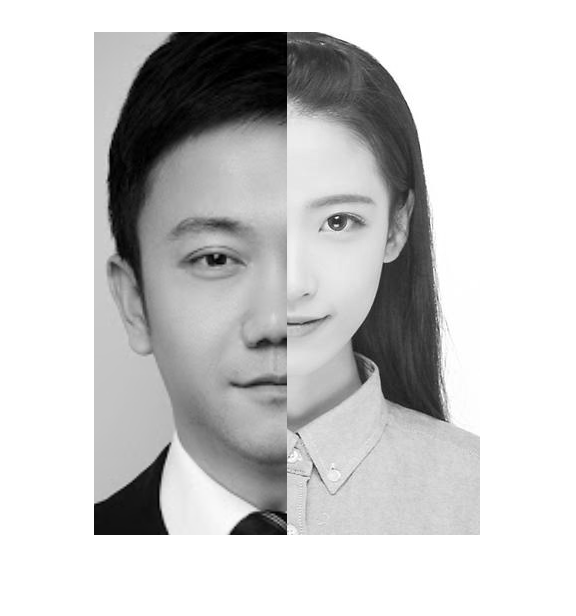

imshow(stitch_img)

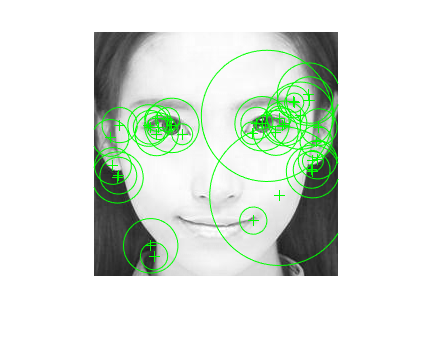

girl  = imread('hw2_files\Q2\girl.jpeg');
man  = imread('hw2_files\Q2\man.jpg');
% Detect faces
faceDetector = vision.CascadeObjectDetector;

bboxes_g = step(faceDetector, girl);
bboxes_m = step(faceDetector, man);
% Select the first face
face_g = girl(bboxes_g(1,2):bboxes_g(1,2)+bboxes_g(1,4),bboxes_g(1,1):bboxes_g(1,1)+bboxes_g(1,3));
face_m = man(bboxes_m(1,2):bboxes_m(1,2)+bboxes_m(1,4),bboxes_m(1,1):bboxes_m(1,1)+bboxes_m(1,3));
[row_g,col_g] = size(face_g);
[row_m,col_m] = size(face_m);
face_m = imresize(face_m, row_g/row_m);

% Detect SURF features
ftrs_g = detectSURFFeatures(face_g);
%Plot facial features.
figure;
imshow(face_g);hold on; plot(ftrs_g);

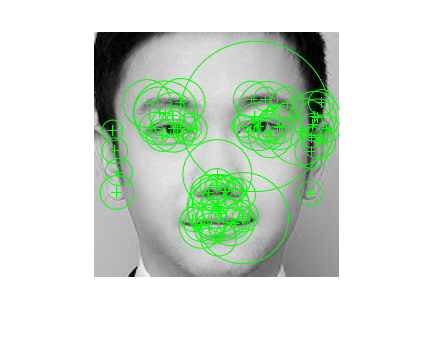


% Detect SURF features
ftrs_m = detectSURFFeatures(face_m);
%Plot facial features.
figure;
imshow(face_m);hold on; plot(ftrs_m);

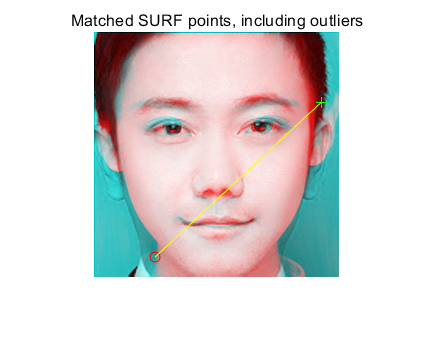


original = face_g;
distorted = face_m;

[ori_row, ori_col] = size(original);
[dis_row, dis_col] = size(distorted);

ptsOriginal = ftrs_g; 
ptsDistorted = ftrs_m; 

% Generate descriptive features
[featuresOriginal,validPtsOriginal] = extractFeatures(original,ptsOriginal); 
[featuresDistorted,validPtsDistorted] = extractFeatures(distorted,ptsDistorted);
% Descriptive feature matching
% TODO: find the min eucidian distance for good match (1st near and 2nd
% near)
index_pairs = matchFeatures(featuresOriginal,featuresDistorted,'Method','Approximate','MaxRatio', 0.9); 


% Matched key points
matchedPtsOriginal = validPtsOriginal(index_pairs(:,1)); 
matchedPtsDistorted = validPtsDistorted(index_pairs(:,2)); 

%Show matching points
figure;
showMatchedFeatures(original,distorted,matchedPtsOriginal,matchedPtsDistorted);
title('Matched SURF points, including outliers'); 


%Estimate geographic transform matrix
tform = estimateGeometricTransform(matchedPtsDistorted,matchedPtsOriginal,'projective'); 

错误使用 estimateGeometricTransform>checkRuntimeStatus (line 183)
matchedPoints1 and matchedPoints2 do not have enough points. The number of points in each set must be at least 4.

出错 estimateGeometricTransform (line 165)
    checkRuntimeStatus(statusCode, status, sampleSize);


[xlim_ori,ylim_ori]=outputLimits(projective2d(eye(3)),[1 ori_col],[1 ori_row]);
[xlim_des,ylim_des]=outputLimits(tform,[1 ori_col],[1 ori_row]);
maxImgSize = max([ori_row,ori_col;dis_row,dis_col]);

xlim = [xlim_ori;xlim_des];
ylim = [ylim_ori;ylim_des];
% Find the minimum and maximum output limits. 
xMin = min([1; xlim(:)]);
xMax = max([maxImgSize(2); xlim(:)]);
yMin = min([1; ylim(:)]);
yMax = max([maxImgSize(1); ylim(:)]);
% Width and height of panorama.
width  = round(xMax - xMin);
height = round(yMax - yMin);
% Initialize the "empty" panorama.
panorama = zeros(height,width);

blender = vision.AlphaBlender('Operation', 'Binary mask', ...
    'MaskSource', 'Input port'); 
%Compute the estimated registration result
xLimits = [xMin xMax];
yLimits = [yMin yMax];
panoramaView = imref2d([height width], xLimits, yLimits);

warpedImage = imwarp(original,projective2d(eye(3)),'OutputView',panoramaView);
mask = imwarp(true(size(original,1),size(original,2)),projective2d(eye(3)) , 'OutputView', panoramaView);
panorama = step(blender, panorama, im2double(warpedImage), mask);

warpedImage = imwarp(distorted,tform,'OutputView',panoramaView);
mask = imwarp(true(size(distorted,1),size(distorted,2)),tform , 'OutputView', panoramaView);
panorama = step(blender, panorama, im2double(warpedImage), mask);

figure; 
imshow(panorama); 